# Exercises 3 (Lectures 5-6)

**Exercise 2. **Generate some data using`x = rand(1,50); y = x + randn(1,50);`. Split the data points in half. Fit a linear model to one half of the data (*y* = *ax* + *b*) and compute the *R*2 value for the goodness-of-fit. Then quantify how well this fitted model predicts the second half of the data, again summarizing performance using *R*2. How do the two values compare? Is the answer the same for other splits of the data?

len = 50;
x = rand(1,len);
y = x + randn(1,len);

% Splitting data
n = length(x);
k = 2;                  % how many parts to use
allix = randperm(n);    % all data indices, randomly ordered
numineach = ceil(n/k);  % at least one part must have this many data points
% Indexes for each of parts
allix = reshape([allix NaN(1,k*numineach-n)],k,numineach);

% Train half
train_x = x(allix(1,:));
train_y = y(allix(1,:));
% Test half
test_x = x(allix(2,:));
test_y = y(allix(2,:));

X = [train_x' ones(length(train_x),1)];
h = inv(X'*X)*X' * train_y';

modelfit_train = X *h;
train_r2 = computeR2(train_y, modelfit_train');

modelfit_test = [test_x' ones(length(test_x),1)] * h;
test_r2 = computeR2(test_y, modelfit_test');

% We can say that the model is unrelaible regarding that n = 50.

fprintf('Training R2: %.2f%%',train_r2);
fprintf('Testing R2: %.2f%%',test_r2);

figure; hold on;
%a = scatter(x,y,'k.');
a_1 = scatter(train_x,train_y,'ro');
a_2 = scatter(test_x,test_y,'go');
b = plot(train_x,modelfit_train,'b-o');
c = plot(test_x,modelfit_test,'r--');
xlabel('x');
ylabel('y');
legend([a_1 a_2 b c], 'Test data','Train data', 'Model fit on train data', 'Model fit on test data')
title(sprintf('y = %.2f*x + %.2f',h(1),h(2)));

**Exercise 3. **Generate some data using `x = rand(1,1000); y = x + randn(1,1000);`. Let's imagine that these data constitute the complete population from which we are sampling. Draw a small sample (*n* = 10) from the population and fit a line that predicts the *y*-values from the *x*-values. Visualize this line on a figure. Repeat this for additional samples, plotting all of the lines on the same figure. How stable is the line across different samples? See what happens when you make the sample size larger (*n* = 100).

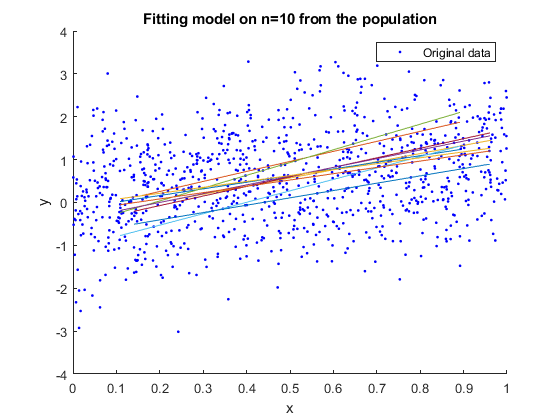


x = rand(1,1000);
y = x+randn(1,1000);

n = 10;
n2=100;
numboots = 10;

x_samples = zeros(numboots, n);
modelfit = zeros(numboots, n);
params = zeros(numboots, 2);

for boot=1:numboots
    
    % prepare data indices
    % rand(1,n) = [0:1](1x100)
    ix = ceil(n*rand(1,n));
    x_samples(boot,:) = x(ix);
    % construct regressor matrix
    X = [x(ix)' ones(n,1)];
    % estimate parameters
    h = inv(X' * X) * X'*y(ix)';
    % evaluate the model
    modelfit(boot,:) = x(ix)*h(1) + h(2);
    % record the parameters
    params(boot,:) = h;
end

% visualize
figure; hold on;
xlabel('x');
ylabel('y');
title('Fitting model on n=10 from the population')


% First, plot our dots
h1 = scatter(x,y,'b.');

% Then draw the lines  for the models fitted on diffirent samples
X = [x(ix)' ones(n,1)];
modelfit_fit  = X * h;

% Plot them all
h2 = plot(x_samples', modelfit');
uistack(h2,'top')

legend([h1], 'Original data')
hold off;

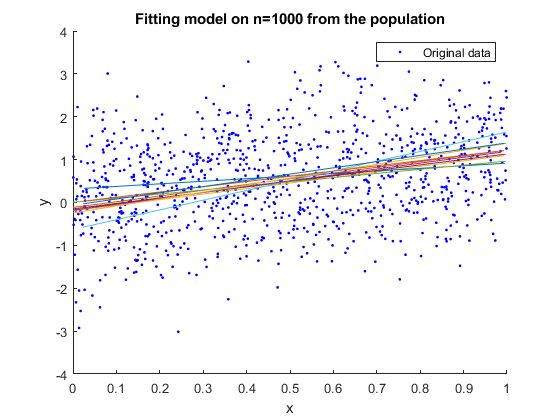


x_samples = zeros(numboots, n2);
modelfit = zeros(numboots, n2);
params = zeros(numboots, 2);

for boot=1:numboots
    
    % prepare data indices
    % rand(1,n) = [0:1](1x100)
    ix = ceil(n2*rand(1,n2));
    x_samples(boot,:) = x(ix);
    % construct regressor matrix
    X = [x(ix)' ones(n2,1)];
    % estimate parameters
    h = inv(X' * X) * X'*y(ix)';
    % evaluate the model
    modelfit(boot,:) = x(ix)*h(1) + h(2);
    % record the parameters
    params(boot,:) = h;
end

% visualize
figure; hold on;
xlabel('x');
ylabel('y');
title('Fitting model on n=1000 from the population')


% First, plot our dots
h1 = scatter(x,y,'b.');

% Then draw the lines  for the models fitted on diffirent samples
X = [x(ix)' ones(n2,1)];
modelfit_fit  = X * h;

% Plot them all
h2 = plot(x_samples', modelfit');
uistack(h2,'top')

legend([h1], 'Original data')
hold off;

**Exercise 1. **Write a function that computes coefficient of determination (*R*2).

function f = computeR2(model,data)
    r2 = 100 * (1 - sum((model - data).^2)/sum((model-mean(model)).^2));
    f = r2;
end